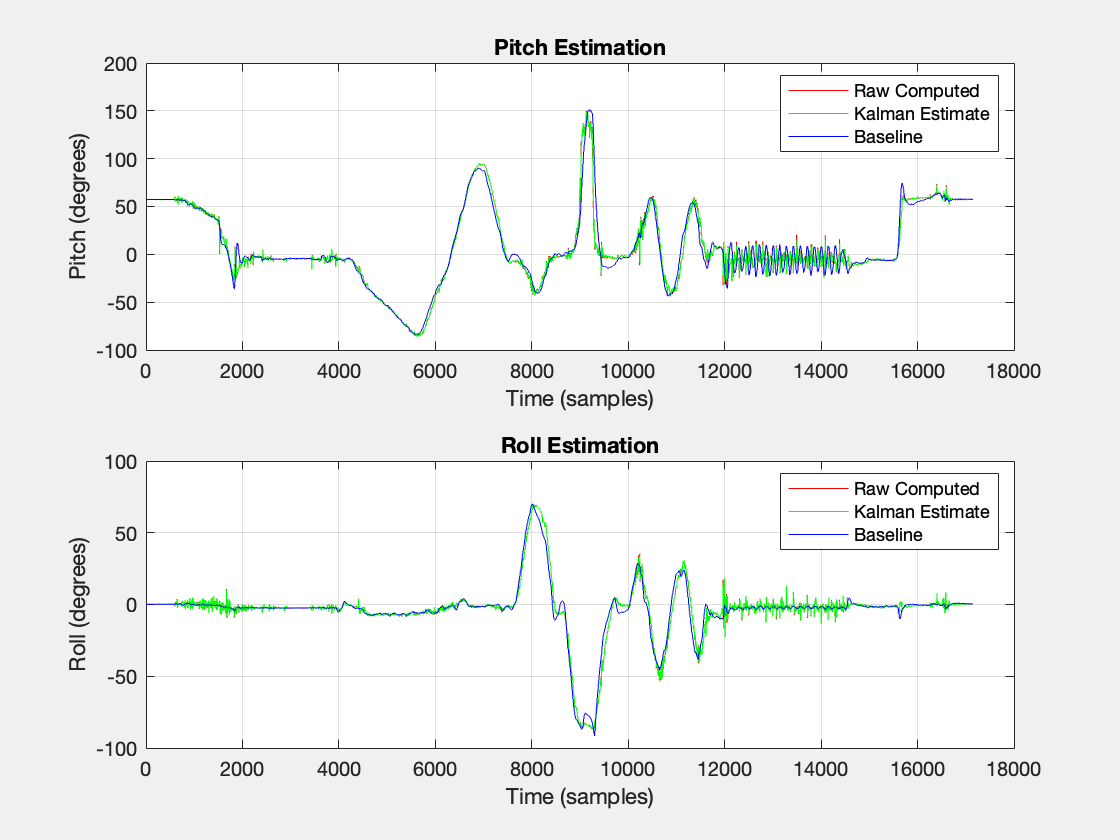

clear all;

% Reads In TimeStamped Accel and Gyro Data. 
% Estimates Roll and Pitch 
% Compares results with raw estimation

filePath = "DataSets/RawIMU.csv";

% Read the CSV file into a table
dataTable = readtable(filePath);

% Extract the necessary columns (accelerometer and gyroscope data)
AX = dataTable.AX;
AY = dataTable.AY;
AZ = dataTable.AZ;
GX = dataTable.GX;
GY = dataTable.GY;
GZ = dataTable.GZ;
PITCH = dataTable.PITCH;
ROLL = dataTable.ROLL;

% Sample time (assuming constant sampling rate from earlier)
SampleTime_ms = diff(dataTable.Timestamp_ms);
SampleTime_s = SampleTime_ms / 1000;  % Convert ms to seconds

% Initialize arrays for pitch and roll estimates
pitch_kest = zeros(length(AX)-1, 1);
roll_kest = zeros(length(AX)-1, 1);

pitch_raw = zeros(length(AX)-1, 1);
roll_raw = zeros(length(AX)-1, 1);


% Kalman filter variables for pitch
pitch_kf = 0;  % initial estimate
pitch_P = 5;   % initial estimate error covariance
pitch_R = 0.03; % measurement noise covariance (accelerometer)
pitch_Q = 0.01; % process noise covariance (gyroscope)

% Kalman filter variables for roll
roll_kf = 0;   % initial estimate
roll_P = 1;    % initial estimate error covariance
roll_R = 0.03;  % measurement noise covariance (accelerometer)
roll_Q = 0.1; % process noise covariance (gyroscope)

for i = 1:length(AX)-1
    % Step 1: Compute pitch and roll from accelerometer (using C-like logic)
    % Compute squared values for normalization (accel data squared for roll)
    ax2 = AX(i) * AX(i);
    ay2 = AY(i) * AY(i);
    az2 = AZ(i) * AZ(i);

    % Raw pitch calculation using accelerometer

    pitch_acc = atan2(-AX(i), AZ(i)) * (180 / pi);  % Convert to degrees
    pitch_raw(i) = pitch_acc;
    % Raw roll calculation using accelerometer
    roll_acc = atan(AY(i) / sqrt(ax2 + az2)) * (180 / pi);  % Convert to degrees
    roll_raw(i) = roll_acc;
    % Step 2: Gyroscope rates (in radians per second)
    gyro_pitch_rate = GX(i);  % Gyroscope pitch rate
    gyro_roll_rate = GY(i);   % Gyroscope roll rate

    % Step 3: Update Kalman filter for pitch
    % Prediction step
    pitch_kf = pitch_kf + gyro_pitch_rate * SampleTime_s(i);  % Integrate the gyroscope data
    pitch_P = pitch_P + pitch_Q;  % Update the error covariance

    % Update step
    K_pitch = pitch_P / (pitch_P + pitch_R);  % Kalman gain
    pitch_kf = pitch_kf + K_pitch * (pitch_acc - pitch_kf);  % Update the estimate
    pitch_P = (1 - K_pitch) * pitch_P;  % Update the error covariance

    % Step 4: Update Kalman filter for roll
    % Prediction step
    roll_kf = roll_kf + gyro_roll_rate * SampleTime_s(i);  % Integrate the gyroscope data
    roll_P = roll_P + roll_Q;  % Update the error covariance

    % Update step
    K_roll = roll_P / (roll_P + roll_R);  % Kalman gain
    roll_kf = roll_kf + K_roll * (roll_acc - roll_kf);  % Update the estimate
    roll_P = (1 - K_roll) * roll_P;  % Update the error covariance

    % Store the estimates
    pitch_kest(i) = pitch_kf;
    roll_kest(i) = roll_kf;
end

% Plot the results
fig = figure;

% Plot for Pitch
subplot(2,1,1); 
plot(pitch_raw, 'r'); hold on;  % Raw computed pitch (from accelerometer)
plot(pitch_kest, 'g');  % Kalman filter pitch estimate
plot(PITCH, 'b');  % Baseline pitch (from dataset)
hold off; grid on;
title('Pitch Estimation');
xlabel('Time (samples)');
ylabel('Pitch (degrees)');
legend('Raw Computed', 'Kalman Estimate', 'Baseline');

% Plot for Roll
subplot(2,1,2);
plot(roll_raw, 'r'); hold on;  % Raw computed roll (from accelerometer)
plot(roll_kest, 'g');  % Kalman filter roll estimate
plot(ROLL, 'b');  % Baseline roll (from dataset)
hold off; grid on;
title('Roll Estimation');
xlabel('Time (samples)');
ylabel('Roll (degrees)');
legend('Raw Computed', 'Kalman Estimate', 'Baseline');

set(fig, "Visible", "on")